## Homework 7- Functions

1) Write an anonymous function which computes the function $h(u,v) = \cos(u) \cos(v)$. Evaluate the value of $h(1,2)$.

h = @(u, v) (cos(u) * cos(v));
h(1, 2)

ans =     -762/3389  

2) Consider the anonymous function f=@(x) x.*exp(-C.*x.^2);. Write a *for* loop that will plot this family of functions on the interval $[-1,1]$ for $C$ in $\{-1, -0.8, -0.6, \dots 1\}$.

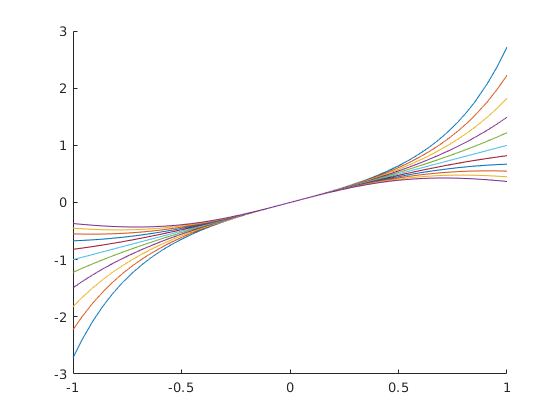

hold on
for C = -1:0.2:1 % for loop only executes once since C is defined as a vector
    f=@(x) x.*exp(-C.*x.^2);
    fplot(f, [-1, 1])
end
hold off

3) Write a function M-file that will compute the function $f(x)=xe^{-Cx^2}$ where the constant C is passed in as a parameter. Save this to a file and then write a *for* loop to create the matrix whose rows are this function evaluated on  interval  -1:.05:1 for $C$ in $\{-1, -0.8, -0.6, \dots 1\}$. 

matrix = [];
for C = -1:0.2:1
    matrix = [matrix;hw7help(-1:.05:1, C)];
end
matrix % makes quite a large matrix

matrix =    -1457/536      -5212/2225     -2713/1341     -1369/782       -927/611      -1519/1154      -689/603      -1563/1576     -7316/8507     -1464/1967     -2118/3299      -848/1539      -583/1242      -595/1504      -323/984       -392/1473      -760/3651      -627/4087      -201/1990      -801/15980        0            801/15980      201/1990       627/4087       760/3651       392/1473       323/984        595/1504       583/1242       848/1539      2118/3299      1464/1967      7316/8507      1563/1576       689/603       1519/1154       927/611       1369/782       2713/1341      5212/2225      1457/536   
   -2161/971      -2071/1059     -1650/959       -903/596      -1136/851      -1168/993      -1527/1474    -10697/11737     -629/786       -358/511       -331/542       -227/429       -546/1201      -188/487       -226/701       -610/2321      -616/2983      -199/1303      -251/2490     -1001/19980        0           1001/19980      251/2490       199/1303       616/2983  

4) Euclid proved that there are an infinite number of primes. He also believed that there are an infinite number of twin primes, primes that differ by 2 (like 5 and 7 or 11 and 13), but no one has been able to prove this conjecture for the past ~2300 years. (It has been proved, somewhat recently, that there are infinitely many prime pairs with gap bounded by 600.)  Write a function that will produce all twin primes between two positive integer inputs  a < b. 

% function defined in external .m file, included with assignment submission
twin_primes_between(30, 100)

ans =       41             43       
      59             61       
      71             73       

twin_primes_between(4000, 5000)

ans =     4001           4003       
    4019           4021       
    4049           4051       
    4091           4093       
    4127           4129       
    4157           4159       
    4217           4219       
    4229           4231       
    4241           4243       
    4259           4261       
    4271           4273       
    4337           4339       
    4421           4423       
    4481           4483       
    4517           4519       
    4547           4549       
    4637           4639       
    4649           4651       
    4721           4723       
    4787           4789       
    4799           4801       
    4931           4933       
    4967           4969       

5) Write your own function  *mymax* that will take a column vector of numbers as input and find the largest entry. The routine should spit out two numbers, the largest entry *val* and its (first) position  *pos* in the vector. Don't use the built-in *max *of Matlab since you will compare your function to the built-in. Test the speed of your routine with the following commands: 

test=rand(1000000,1); tic; [val,pos]=mymax(test);toc

Elapsed time is 0.003540 seconds.


and compare that to the built-in:

tic;[val,pos]=max(test);toc

Elapsed time is 0.001200 seconds.


% the built-in function is roughly an order of magnitude faster

Actually, timings determined by tic, toc  for commands or programs which only take a few milliseconds are not very reliable, since the processor might have given some system command a little bit of time. To get a better idea, run the command a few hundred times and compute the average. (Even so you may see some variation.)

tic; for j=1:500 [val,pos]=mymax(test);end; toc

Elapsed time is 1.483911 seconds.


tic; for j=1:400 [val,pos]=max(test);end; toc

Elapsed time is 0.272290 seconds.


% yep, roughly an order of magnitude faster

6) One function file may contain additional function definitions which are called in the evaluation of the main function. These are called local functions and are only available within the function file (can't be called directly from the command line).

Write a function file ***rootfind.m*** which takes a function handle *funhandle* to a scalar function defined for all real numbers an interval [a,b] and a positive integer n and determines for  how many subintervals [a+(j-1)*(b-a)/n, a+j*(b-a)/n] there is a change of sign of funhandle between the endpoints. Make the determination of the sign change a local function *signchange* within the main function. The function *signchange* should take a vector v of length n and return a vector of length (n-1) whose jth entry is one if v(j) and v(j+1) have opposite signs and zero otherwise. (Note that not all sign changes are sure to be found since if the values were -1,0,1 at successive endpoints then over the union of the two subintervals there is a sign change but not over either of the smaller intervals.)  Your function should give an error if the interval endpoints are equal a=b, and should also work whether a>b or a<b.

%testing rootfind
f = @testfun

f = function_handle with value:
    @testfun

asdf = rootfind(f, -2, 6, 30) % gives the proper result!

asdf =        3       

function y = testfun(x)
y = x.^3 - 6.*x.^2 + 4.*x + 12;
end

Below are copies of the .m functions I wrote as per the instructions in lecture:

% hw7help
%{
function out = hw7help(x, c)
    out = x .* exp(-c .* x .^ 2);
end
%}


% mymax.m
%{
function [maxVal, index] = mymax(colVec)
    index = 1;
    for i = 1:length(colVec)
        if colVec(i, 1) > colVec(index, 1)
            index = i;
        end
    end
    
    maxVal = colVec(index, 1);
end
%}


% rootfind.m
%{ 
function changes = rootfind(funhandle, a, b, n)
    % if interval is measure 0, don't do anything
    if a == b 
        fprintf("ERROR: interval has length 0")
        return
    end
    
    % make sure the ordering of interval is correct
    low = min(a, b);
    high = max(a, b);
    
    x = linspace(low, high, n);
    y = funhandle(x);
    changes = length(find(signchange(y)));
end

function w = signchange(v)
    w = [];
    for i = 1:(length(v) - 1)
        if v(i) > 0 && v(i + 1) < 0
            w = [w 1];
        
        elseif v(i) < 0 && v(i + 1) > 0
            w = [w 1];
        else
            w = [w 0];
        end
    end
end
%} 


% twin_primes_between.m
%{
function outMatrix = twin_primes_between(a, b)
    outMatrix = [];
    
    if (b - a) < 2 
        return
    end
    
    for i = a:(b-2)
        if isprime(i) && isprime(i + 2)
            outMatrix = [outMatrix; i i+2];
        end
    end    
end
%}
